close all
clear
clc

准备工作

N = 1000;
KEEP = 50;
[t,omg,FT,IFT] = prefourier([-5,5],N,[-10*pi,10*pi],1000);

生成三角频谱，逆变换得到时域波形

G = tripuls(omg/5);
g = IFT*G;

对时域波形进行冲激抽样，再将每个样值替换为一个矩形脉冲，即得到零阶抽样保持

gtemp = 0*g;
gtemp(1:KEEP:N) = g(1:KEEP:N);
g1 = filter(ones(1,KEEP),1,gtemp);

变换得到零阶抽样保持信号的频谱

G1 = FT*g1;

绘图

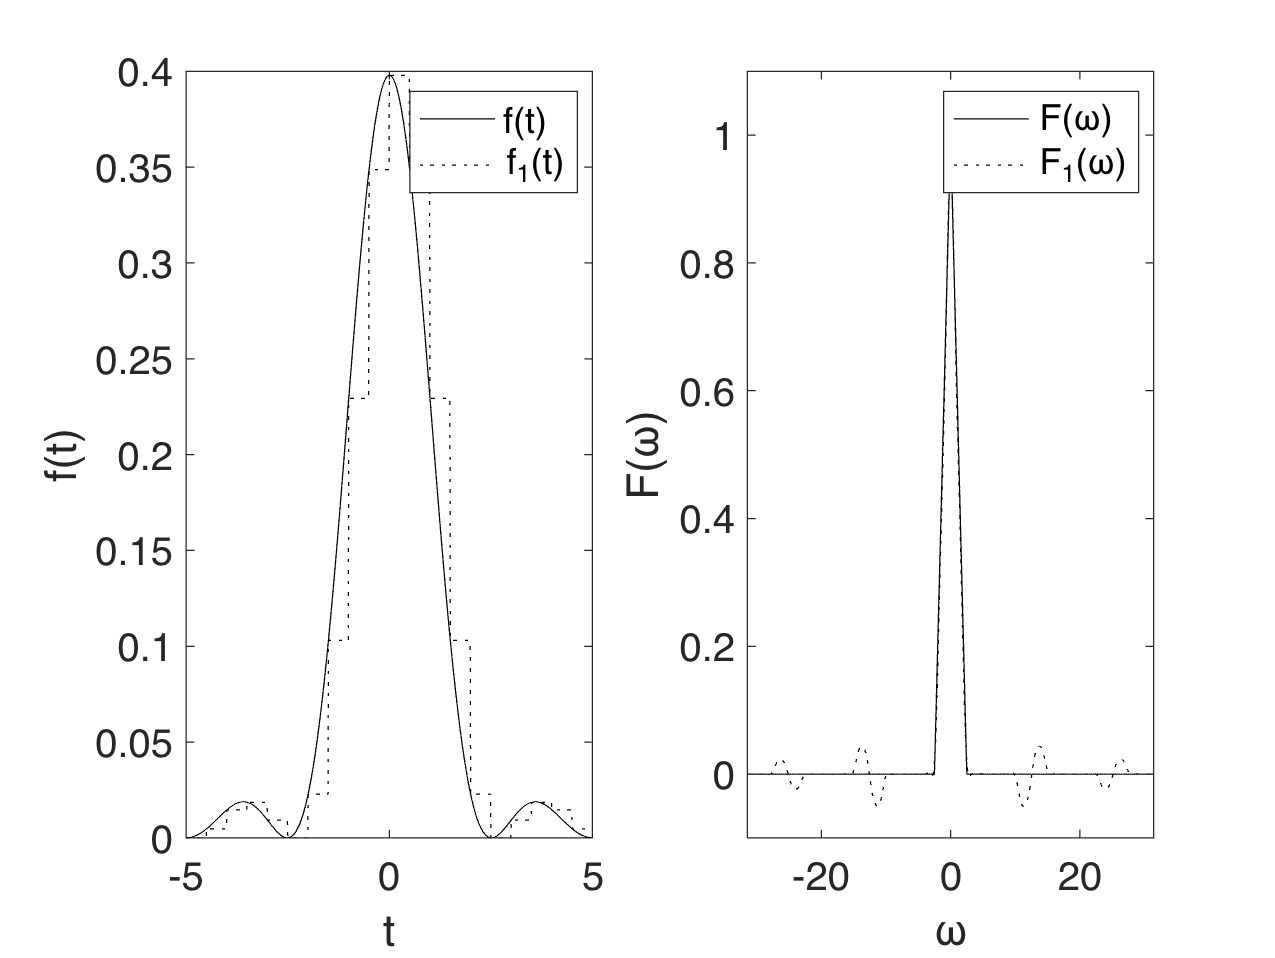

figure;
subplot(1,2,1), hold on, box on;
plot(t,real(g),'k-',t,real(g1),'k:');
set(gca,'FontSize',16);
xlabel('t');
ylabel('f(t)');
legend('f(t)','f_1(t)');

subplot(1,2,2), hold on, box on;
plot(omg,real(G),'k-',omg,real(G1),'k:');
set(gca,'FontSize',16,'XLim',[-10*pi,10*pi],'YLim',[-0.1,1.1]);
xlabel('\omega')
ylabel('F(\omega)');
legend('F(\omega)','F_1(\omega)');